# Homework 05 - System Analysis

Please add your name, section, and semester information to the fields below

StudentName = "Edward Ramirez"; % First Last
Section = "A09"; % ex. A01
Semester = "Spring 2025"; % ex. Spring 2025

## Background

In this block you will be measuring the frequency response of the mass-spring-damper (MSD) system to determine the system parameters which best meet a client's specifications. You will then model the system forces and displacements at its damped natural frequency. Additionally, you will determine the models of the system parameters of mass, spring constant, and damping coefficient.  

 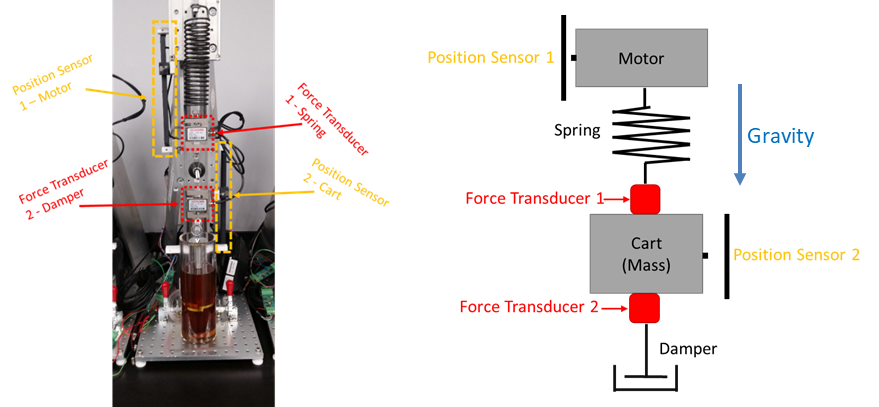

*Figure 1: Mass-spring-damper system (left) and schematic (right) showing location of force and position senesors.*

The MSD test system is instrumented with several sensors to determine the system displacement and forces due to a varying frequency input (Figure 1). The input into the system consists of a moving base which is attached to a rotating motor whose frequency can be controlled. The position of the base, $x_1$, is measured using Position Sensor 1. The moving base is attached to one end of a spring whose other end is attached to a track-guided cart of variable mass. The force imparted on the cart from the spring, $F_1$, is measured by Force Transducer 1. Attached to the bottom cart is a viscous damper whose damping can be varied. The force imparted on the cart from the damper, $F_2$, is measured by Force Transducer 2. The resulting amplitude of the displacement of the cart is dependent on the mass, the spring constant, the damping, and the frequency of the motor. The cart position, $x_2$, is measured using Position Sensor 2.

## Data

A sample dataset, *Homework_5_Data.mat*, that you will use in this homework analysis can be found in the assignment on Canvas.

load( 'Homework_5_Data.mat' );

## Transducer Calibration and Uncertainty

All four sensors have been calibrated by the manufacturer. The specifications for the gain and calibration uncertainty for the force transducers and the gain and resolution for the position sensor are provided below. However, the offset for each sensor must still be determined to complete the calibration equations. The manufacturer's specifications for the sensors are listed below:

% Force and Position Sensor Specifications
G_F_N_V = 26.75; % N/V, spring force transducer gain
u_F_spec_N = 0.2; % N, spring force transducer calibration uncertainty
V_F_min_V = 0; % V, spring force transducer minimum voltage
V_F_max_V = 5; % V, spring force transducer maximum voltage

G_D_m_V = 0.056; % m/V, position sensor gain
r_D_spec_m = 0.000014; % m, position sensor resolution

### Force Sensor Offset Experiment

The equation for the spring force sensor calibration is of the form:


$$F_1 \left(V\right)=G_{F_1 } \cdot V_1 +F_{0,1}$$
 

where the spring force, $F_1$, is assumed to linearly related to the spring force voltage measured by the ELVIS board, $V_1$, by the sensor gain, $G_{F_1 }$, and the apparent force offset, $F_{0,1}$. The apparent force offset can be determined experimentally by measuring the voltage with no force being applied. *Homework_5_Data.mat* contains a sample set of offset force experiment voltage data, $V_{1,0}$, where the voltage was collected for a short period of time.

% Spring force offset experiment data
V_1_0_V; % V, spring force offset voltage data

#### Problem 1

What is the mean offset force of the sensor, $F_{0,1}$, in **Newtons**? (*Hint: It should be between -55 and -45 N.*)

% Code here to solve for F_0_1_N
F_0_1_N = mean(V_1_0_V) * G_F_N_V;

% Print answer
fprintf( 'F_0_1  = %.3g N\n', F_0_1_N ); 

F_0_1  = 50.7 N


#### Problem 2

What are the minimum, $F_{1,\min }$, and maximum, $F_{1,\max }$, forces the spring force sensor is capable of measuring in **Newtons**? (*Hint: They should be between -55 and 90 N.*)

% Code here to solve for F_1_min_N and F_1_max_N
F_1_min_N = V_F_min_V * G_F_N_V + F_0_1_N;
F_1_max_N = V_F_max_V * G_F_N_V + F_0_1_N;


% Print answer
fprintf( 'F_1_min = %.3g N, F_1_max = %.3g N\n', F_1_min_N, F_1_max_N ); 

F_1_min = 50.7 N, F_1_max = 184 N


#### Force Sensor Offset Accuracy Uncertainty

#### Problem 3

What is the sample standard deviation of mean the offset force, $s_{\bar{F_{0,1} } }$, in **Newtons**? (*Hint: It should be between 0.05 and 0.15 N.*)

% Code here to solve for s_bar_F_0_1_N
s_bar_F_0_1_N = std(V_1_0_V) * G_F_N_V / sqrt(length(V_1_0_V));

% Print answer
fprintf( 's_bar_F_0_1  = %.3g N\n', s_bar_F_0_1_N ); 

s_bar_F_0_1  = 0.0829 N


#### Problem 4

What is the uncertainty for the force offset, $u_{F_{0,1} }$, for a K = 2 (95.4%) level of certainty in **Newtons**? (*Hint: It should be between 0.15 and 0.25 N.*)

% Code here to solve for u_F_0_1_N
u_F_0_1_N = 2 * s_bar_F_0_1_N;

% Print answer
fprintf( 'u_F_0_1  = %.3g N\n', u_F_0_1_N );

u_F_0_1  = 0.166 N


### Force Sensor Acquisition Precision Uncertainty

When acquiring the voltage from the force sensor, the voltage resolution of the acquisition system can affect the uncertainty of the measurement. Below is the voltage resolution of the ELVIS III board for the voltage range that will be measured in lab. 

% NI ELVIS III acquisition specifications
r_V_V = 0.3052E-3; % V, ELVIS III voltage resolution

#### Problem 5

What is the uncertainty for the ELVIS III voltage, $u_V$, for a K = 2 (95.4%) level of certainty in** Volts**? (*Hint: It should be between 0.0001 and 0.0002 V.*)

% Code here to solve for u_F_0_1_N
u_V_V = 2 * r_V_V;

% Print answer
fprintf( 'u_V = %.3g V\n', u_V_V ); 

u_V = 0.00061 V


#### Problem 6

What is the force precision uncertainty from the gain, $u_{F_{G,1} }$, for a K = 2 (95.4%) level of certainty in** Newtons**? (*Hint: It should be between 0.004 and 0.005 N.*)

% Code here to solve for u_F_G_1_N
u_F_G_1_N = u_V_V * G_F_N_V;

% Print answer
fprintf( 'u_F_G_1 = %.3g N\n', u_F_G_1_N ); 

u_F_G_1 = 0.0163 N


### Force Sensor Total Uncertainty

For single data points, the uncertainty of the measurement is a combination of the all the sources of force uncertainty including the precision uncertainty from acquisition, the accuracy uncertainty from the offset, and the calibration uncertainty from the manufacture.

#### Problem 7

What is the total force uncertainty from the spring force transducer, $u_{F_{1,\textrm{sensor}} }$, for a K = 2 (95.4%) level of certainty in** Newtons**? (*Hint: It should be between 0.20 and 0.30 N.*)

% Code here to solve for u_F_1_sensor_N
u_F_1_sensor_N = sqrt(u_F_G_1_N^2 + u_F_0_1_N^2 + u_F_spec_N^2);

% Print answer
fprintf( 'u_F_1_sensor = %.3g N\n', u_F_1_sensor_N );

u_F_1_sensor = 0.26 N


## Experimental System Modeling

In lab, you will be characterizing the mass-spring-damper system and components by collecting time series data of the motor position ($D_1$), cart position ($D_2$), spring force ($F_1$), and damper force ($F_2$) for different cart masses and damper settings using the “Force Experiment” tab in the VI.  For each mass-damper combination, you will collect data in a single, continuous run, during which you will change motor speed settings to see how the system responds to different input frequencies. Multiple runs and a large amount of data will be collected during this lab, which will make it difficult to process unless you use good programing and data management techniques. 

### Sinusoidal Curve Fitting

We want to analyze data for various combinations of masses, damping coefficients, and motor speeds. The gain and phase lag for each setting will then be calculated to map the response of the system. How can we do this analysis in a quick and non-subjective manner? From mass-spring-damper theory, it is expected that the displacement ($D_1$) and forces acting on the cart ($F_1$ & $F_2$) will be sinusoidal like the motor input ($D_2$):


$$D\left(t\right)=\textrm{Xsin}\left(\omega t+\phi \right)+X_0$$



$$F\left(t\right)=\textrm{Fsin}\left(\omega t+\phi \right)+F_0$$


Using this assumption, the data can be fit to a sinusoidal function to determine the amplitude, frequency, and phase computationally. These regression values can then be used to calculate the displacement gain and phase lag at a given frequency.

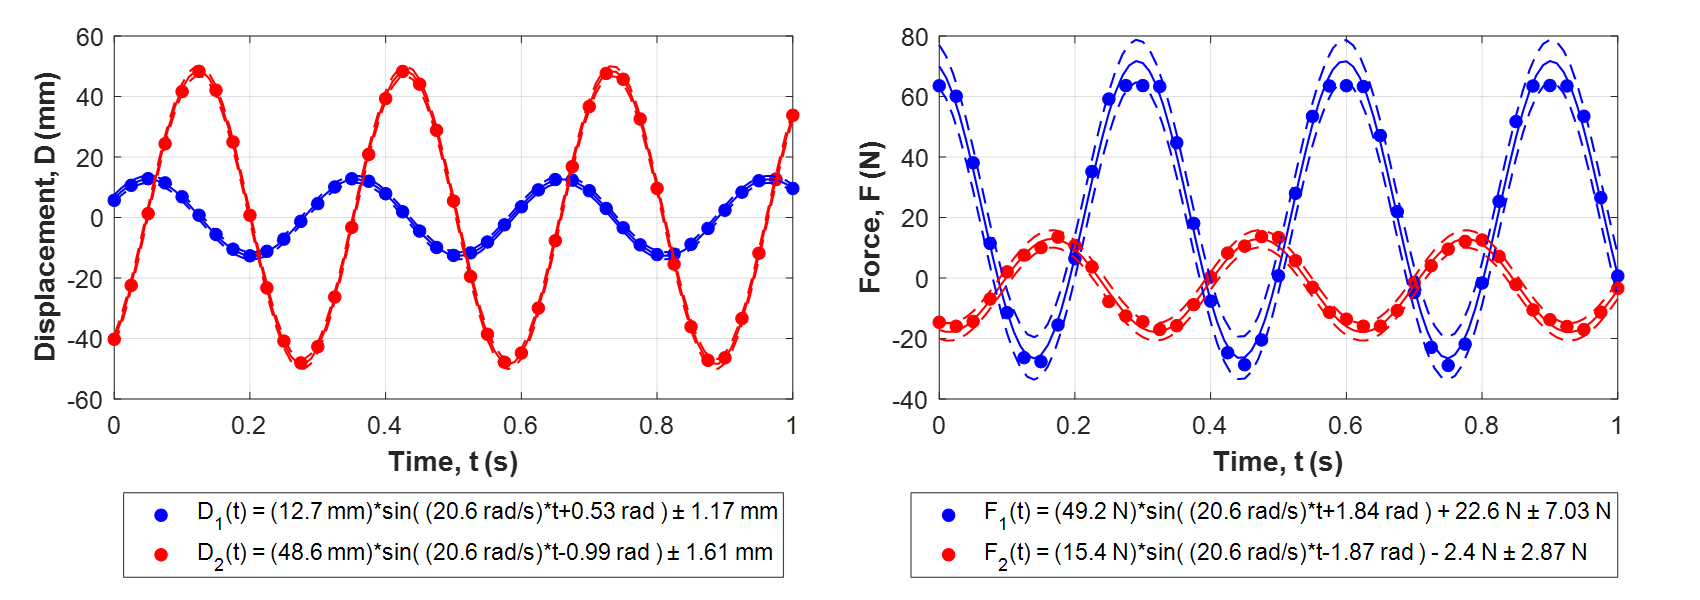

*Figure 2: Example displacement and force sinusoidal regression.*

Since you will be processing a large amount of data, you will want to create two functions which will do this for you: one will do a sinusoidal regression on time series data (position, velocity, acceleration, and forces) and a second will call the first to calculate the system response using the position data. This section of the homework assignment will walk you through some of the data processing and regression analysis which will be needed to do this. A sample set of data time, force, and position data for a single frequency, mass, and damper combination can be found in *Homework_5_Data.mat:*

% Sample regression data set
t_sin_s; % s, time
D_1_sin_mm; % mm, motor position from position sensor 1
D_2_sin_mm; % mm, cart position from position sensor 2
F_1_sin_N; % N, spring force from force sensor 1
F_2_sin_N; % N, damper force from force sensor 2

The spring force data, $F_1$, will be used for this section to develop the regression code and a function to perform the analysis. The function will then be checked using the damper force and motor & cart position data.

MATLAB has a built-in fit type called ***‘sin1’*** which will calculate the amplitude, frequency, and phase from the data. However, due to the periodic nature of the data and the fact that the ***‘sin1’*** fit type does not calculate an offset, the ***fit() ***function can easily converge on an incorrect solution without some preconditioning of the data. The first step in processing the data for each motor setting is to shift the time data to start at zero. This will improve the consistency with which the phase is calculated (since the signal is periodic, there are an infinite number of correct solutions for the phase).

#### Problem 8

What is the start time of the data segment, $t_{0,1,\sin }$, in seconds? *(Hint: LabVIEW typically exports the data in reverse chronological order. It should be between 19 and 20 s.) *

% Code here to solve for t_0_sin_s
t_0_sin_s = min(t_sin_s);

% Print answer
fprintf( 't_0_sin = %.3g s\n', t_0_sin_s );

t_0_sin = 19.3 s


#### Problem 9

Use the segment start time to re-zero the time data so the segment starts at 0 seconds. 

% Code here to shift time data
t_sin_shifted_s = t_sin_s - t_0_sin_s;

The next step is to determine the offset of the data by calculating the mean value. This will then be used to remove the offset in the data since it will not be calculated by ***‘sin1’*** fit type.

#### Problem 10

What is the mean force/offset for the spring force, $F_{0,1,\sin }$, in **Newtons**? (*Hint: It should be between 15 and 20 N.*)

% Code here to solve for F_0_1_sin_N
F_0_1_sin_N = mean(F_1_sin_N);

% Print answer
fprintf( 'F_0_1_sin_N = %.3g N\n', F_0_1_sin_N ); 

F_0_1_sin_N = 18.5 N


#### Problem 11

Use the mean force value to re-zero the spring force data. (*Hint: The mean value should now be zero.)*

% Code here to shift spring force data
F_1_shifted_N = F_1_sin_N - F_0_1_sin_N;

% Print answer
fprintf( 'F_1_shifted_N mean = %.3g N\n', mean( F_1_shifted_N ) ); 

F_1_shifted_N mean = -2.57e-15 N


With the data now shifted in time and the offset removed, the ***‘sin1’*** fit type can be used to calculate the signal parameters.

#### Problem 12

Using the ***fit() ***function with the **‘*****sin1’*** fit type, what is the amplitude, $A_{F_1 }$, in **Newtons**, the frequency, $f_{F_1 }$, in **hertz**, and the phase, $\phi_{F_1 }$, in **degrees** of the spring force? *(Hint: The ‘sin1’ fit type will return coefficients in terms of radians per second for the frequency and radians for the phase. Save both the fit and goodness object. The amplitude should be between 40 and 50 N, the frequency between 2 and 4 Hz, and the phase between 120 and 130 deg.) *

% Code here to solve for A_F_1_N, f_F_1_Hz, & phi_F_1_deg
fit_sin = fit(t_sin_shifted_s, F_1_shifted_N, 'sin1')

fit_sin =      General model Sin1:
     fit_sin(x) =  a1*sin(b1*x+c1)
     Coefficients (with 95% confidence bounds):
       a1 =       46.65  (46.43, 46.87)
       b1 =        19.3  (19.3, 19.3)
       c1 =       2.241  (2.232, 2.251)

A_F_1_N = fit_sin.a1;
omega_F_1_rad_s = fit_sin.b1;
phi_F_1_rad = fit_sin.c1;
f_F_1_Hz = omega_F_1_rad_s / (2 * pi);
phi_F_1_deg = rad2deg(phi_F_1_rad);

% Print answers
fprintf( 'A_F_1 = %.3g N\n', A_F_1_N ); 

A_F_1 = 46.6 N


fprintf( 'f_F_1 = %.3g Hz\n', f_F_1_Hz ); 

f_F_1 = 3.07 Hz


fprintf( 'phi_F_1 = %.3g deg\n', phi_F_1_deg );

phi_F_1 = 128 deg


#### Problem 13

What is the experimental uncertainty of the fit, $u_{F_{1,\textrm{model}} }$, for a K = 2 (95.4%) level of certainty in** Newtons**? (*Hint: It should be between 2.0 and 3.0 N.*)

% Code here to solve for u_F_1_model_N
u_F_1_model_N = 2 * std(F_1_shifted_N - feval(fit_sin, t_sin_shifted_s));

% Print answer
fprintf( 'u_F_1_model = %.3g N\n', u_F_1_model_N );

u_F_1_model = 2.22 N


### Sinusoidal Fit Function

You will need to perform this analysis multiple times as you collect data during your experiments. It will be extremely helpful to functionalize this code so that it can be reused. It will also be called in a later function which will also help you perform your analysis.

Write a function that takes in a time vector, $t$, and a single data vector, $x$, as inputs (i.e. $t_{\sin }$ & $F_{1,\sin }$ for this example) and outputs the amplitude, $A$, the frequency, $f$, in hertz, the phase, $\phi$, in degrees, the offset, $X_0$, and the fit object and goodness statistics. There is a section at the end of this Live Script for functions.

#### Problem 14

Using your function, what is the amplitude, $A_{F_2 }$, in **Newtons**, the frequency, $f_{F_2 }$, in **hertz**, the phase, $\phi_{F_2 }$, in **degrees, **and the offset, $F_{0,2}$, of the damper force, $F_{2,\sin }$?  (*Hint: The amplitude should be between 15 and 25 N, the frequency between 2 and 4 Hz, the phase between 80 and 100 deg, and the offset between -1 and 1 N.) *

% Code here to solve for A_F_2_N, f_F_2_Hz, phi_F_2_deg, & F_0_2_N using
% your function
[ A_F_2_N, f_F_2_Hz, phi_F_2_deg, F_0_2_N, fit_F_2 ] = fitSinusoidal(t_sin_s, F_2_sin_N);

A_F_2 = 83.6 N
f_F_2 = -0.000366 Hz
phi_F_2 = -17.2 deg
F_0_2 = 28.8 N


% Print answers
fprintf( 'A_F_2 = %.3g N\n', A_F_2_N ); 

A_F_2 = 83.6 N


fprintf( 'f_F_2 = %.3g Hz\n', f_F_2_Hz ); 

f_F_2 = -0.000366 Hz


fprintf( 'phi_F_2 = %.3g deg\n', phi_F_2_deg );

phi_F_2 = -0.3 deg


fprintf( 'F_0_2 = %.3g N\n', F_0_2_N );

F_0_2 = 28.8 N


#### Problem 15

Plot the original damper force data in **Newtons** versus time in **seconds** and include the regression fit line for the first 2 seconds of data. *(Hint: Remember the force offset in your regression data and the time shift! It is helpful to create a new time vector for plotting the regression to smooth out the fit line.)*

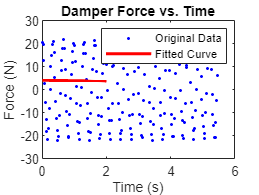

% Code here to plot F_2_sin_N vs t_sin_s 
t_fit_s = linspace(min(t_sin_shifted_s), min(t_sin_shifted_s) + 2, 1000);
F_2_fit_N = feval(fit_F_2, t_fit_s);
figure;
plot(t_sin_shifted_s, F_2_sin_N, 'b.', 'DisplayName', 'Original Data');
hold on;
plot(t_fit_s, F_2_fit_N, 'r-', 'LineWidth', 2, 'DisplayName', 'Fitted Curve');
hold off;
legend;
xlabel('Time (s)');
ylabel('Force (N)');
title('Damper Force vs. Time');

### System Response

With individual sensor data models created, the system displacement transmissibility response can be calculated for a given frequency. You will have to conduct several experiments to map the response versus frequency over the required input range. Since the response calculation will repeated many, many times you will now develop the code and then a function to do this.

#### Problem 16

Using your function from Problem 14, what is the frequency, $f$, in **Hertz**, the amplitudes, $X_1$ & $X_2$, in **millimeters** and phases, $\phi_{x_1 }$ & $\phi_{x_2 }$, in **degrees** for the motor, $D_{1,\sin }$, and cart displacements, $D_{2,\sin }$? *(Hint: The frequency should be between 2 and 4 Hz and the amplitudes should be between 10 and 30 mm. The *$\phi_{x_1 }$ *should be between 40 and 60 degrees and *$\phi_{x_2 }$* should be between -30 and -10 degrees*.* Make sure to shift the time to start at 0 s if your function does not.)*

% Code here to solve for f_Hz, X_1_mm, phi_x_1_deg, X_2_mm, & phi_x_2_deg
[ f_Hz, X_1_mm, phi_x_1_deg, X_2_mm, phi_x_2_deg, ~ ] = fitSinusoidal(t_sin_s, D_1_sin_mm);

A_F_2 = 0.073 N
f_F_2 = -0.16 Hz
phi_F_2 = 1.75e+04 deg
F_0_2 = 206 N


% Print answers
fprintf( 'f = %.3g Hz\n', f_Hz );

f = 0.073 Hz


fprintf( 'X_1 = %.3g mm, phi_x_1 = %.3g deg\n', X_1_mm, phi_x_1_deg ); 

X_1 = -0.16 mm, phi_x_1 = 305 deg


fprintf( 'X_2 = %.3g mm, phi_x_2 = %.3g deg\n', X_2_mm, phi_x_2_deg );

X_2 = 206 mm, phi_x_2 = 206 deg


#### Problem 17

What is the gain (displacement transmissibility), $G=\left|X_2 \right|/\left|X_1 \right|$, of the system? *(Hint: The gain should be between 1 and 3 mm/mm.)*

% Code here to solve for G
G = abs(X_2_mm) / abs(X_1_mm);

% Print answer
fprintf( 'G = %.3g mm/mm\n', G );

G = 1.28e+03 mm/mm


#### Problem 18

What is the phase lag, $\phi$, of the system in **degrees**? *(Hint: The phase lag is between -60 and -80 degrees. By convention the phase lag is negative if the output lags the input. Due to how the phase is calculated in the regression, you may need to shift the result by a period to match this convention.)*

% Code here to solve for phi_sin_deg
phi_deg = phi_x_2_deg.phi - phi_x_1_deg;
if phi_deg > 0
    phi_deg = phi_deg - 360;
end

% Print answer
fprintf( 'phi = %.3g deg\n', phi_deg );

phi = 0 deg


#### Problem 19

Write a function that takes in the time, $t$, motor position, $D_1$, and cart position, $D_2$, vectors as inputs and outputs the frequency, $f$, in Hertz, the gain, $G$, and the phase lag, $\phi$, in degrees of the system. You should be able to repurpose your code from the previous problems. There is a section at the end of this Live Script for functions.

Using your function, verify the frequency, $f$, in **Hertz**, the gain, $G$, and phase lag, $\phi$, in **degrees** using the motor and cart displacement data. *(Note: You will need to use this function multiple times in your analysis. Verify that its performs the analysis correctly, especially the phase lag calculation.)*

% Code here calling function to solve for f
[f_Hz, G, phi_deg] = systemResponseFunction(t_sin_s, D_1_sin_mm, D_2_sin_mm);

A_F_2 = 0.073 N
f_F_2 = -0.16 Hz
phi_F_2 = 1.75e+04 deg
F_0_2 = 206 N
A_F_2 = 0.073 N
f_F_2 = -0.16 Hz
phi_F_2 = 1.75e+04 deg
F_0_2 = 206 N


% Print answer
fprintf( 'f = %.3g Hz\n', f_Hz );

f = 0.073 Hz


fprintf( 'G = %.3g\n', G );

G = 1.28e+03


fprintf( 'phi = %.3g deg\n', phi_deg );

phi = 0 deg


### Data Segmentation and Frequency Response

You will collect several sets of experiments where the frequency is varied for a constant mass and damper setting. The output of each experiment will be a single data set which must be segmented to process each frequency separately. It is expected that the gain and phase lag of the cart will change with frequency. Since the motor displacement amplitude ($D_1$) is fixed by the motor stroke, the cart position vector ($D_2$) can be used to determine when the frequency changes. Figure 3 shows a sample plot of cart displacement data versus time. The changes in amplitude associated with the changes with frequency can be used to segment the data. Segmenting the datasets into separate frequency experiments efficiently will be helpful in processing the large amount of data collected during the experiments.

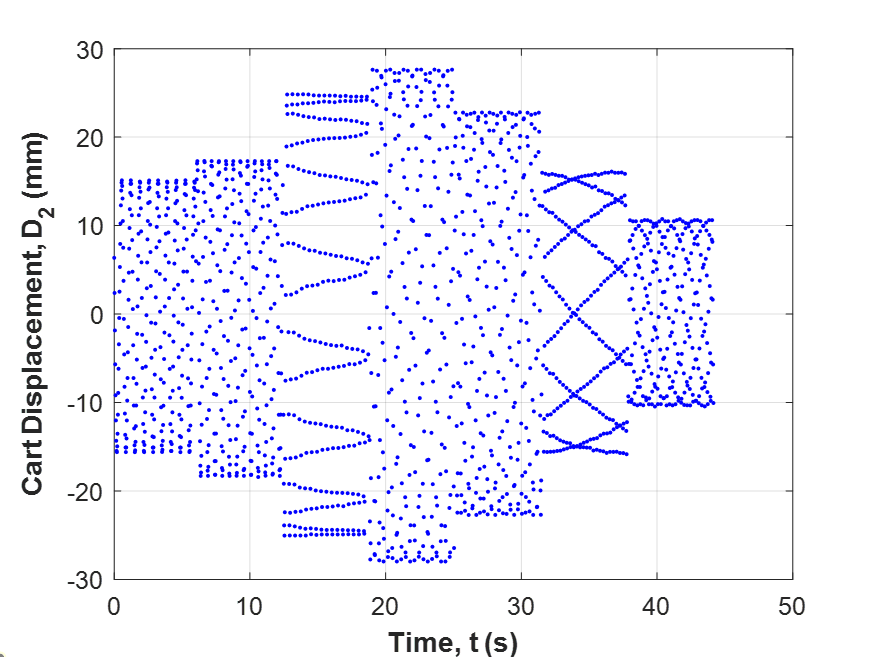

*Figure 3: Cart displacement versus time. Changes in frequency can be determined by the changes in the cart amplitude.*

A sample set of data time, force, and position data for a single mass and damper combination, but multiple frequencies can be found in *Homework_5_Data.mat:*

% Sample experiment data set
t_exp_s; % s, time
D_1_exp_mm; % mm, motor position from position sensor 1
D_2_exp_mm; % mm, cart position from position sensor 2
F_1_exp_N; % N, spring force from force sensor 1
F_2_exp_N; % N, damper force from force sensor 2

#### Problem 20

Using the cart position data ($D_2$), segment the time, position, and force data into seven segments using either the provided *segmentData()* function or your own code. Each data segment is approximately 5 seconds of steady state data each but may have transient periods between settings which should not be used in analysis. For each data segment, calculate the frequency in **Hertz**, the gain, and the phase lag in **degrees** using your function from Problem 19.

Create a Bode plot of gain and phase lag versus frequency. *(Hint: The 4th segment has a frequency between 2.75 and 3.25 Hz, a gain between 2.0 and 2.5, and phase lag between -60 and -80 degrees.)*

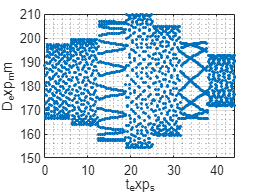

Select regions for segment boundaries on figure
Use the polygon tool and double-click to finish the selection.


'drawpolygon' requires Image Processing Toolbox.

Error in segmentData (line 19)
        roi = drawpolygon('Label','Select Segment');

% Code here to segment the data and create Bode plot of gain and phase lag
% versus frequency.
data_segments = segmentData(t_exp_s, D_2_exp_mm);

frequencies = zeros(1, 7);
gains = zeros(1, 7);
phases = zeros(1, 7);

for i = 1:7
    [frequencies(i), gains(i), phases(i)] = systemResponseFunction(data_segments(i).time, data_segments(i).D1, data_segments(i).D2);
end

figure;
subplot(2,1,1);
semilogx(frequencies, gains, 'bo-', 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('Gain (mm/mm)');
title('Bode Plot: Gain vs. Frequency');
grid on;

subplot(2,1,2);
semilogx(frequencies, phases, 'ro-', 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('Phase Lag (deg)');
title('Bode Plot: Phase Lag vs. Frequency');
grid on;

## Component Models

In addition to determining system models based upon the response of the system, you will also create models of the mass, spring, and damper. These can then be used to predict the forces acting upon the cart as well as the system response versus frequency from the theoretical models. 

### Mass

For part of your experiment, you will be adding masses to your apparatus to change the system dynamics. To understand the dynamics of the system during operation, the total mass of the moving parts (cart, added masses, and damper) needs to be determined. To do this, you will run a force experiment in LabVIEW with the cart loaded and the damper attached, without the motor running. Since the system is static, the spring force, $F_1$, will be equal to the weight of the moving parts. The mass of the moving parts can then be determined by averaging the spring force over a series of measurements. A sample set of static spring force data for a mass used in the experimental data can be found in *Homework_5_Data.mat:*

% Sample static test data set
F_1_static_N; % N, spring force from force sensor 1 during static test
g = 9.81; % m/s^2, assumed gravitational acceleration

#### Problem 21

Using the data from the static test, what is the mass of the moving parts, $m$, in **kilograms**? *(Hint: The mass of the moving parts should be between 1.5 and 2.5 kg.)*

% Code here to solve for m_kg
m_kg = mean(F_1_static_N) / g;

% Print answer
fprintf( 'm = %.3g kg\n', m_kg );

### Spring Constant

The spring constant and damper coefficient will be determined using dynamic testing data at a single frequency. The same data used for Problems 8 through 15 (which corresponds to the 4th segment of the experimental data) will be used for this sample homework analysis.

The spring will be assumed to be linear and therefore the force proportional to the spring displacement:


$$F_1 =-k\cdot D_{\textrm{spring}}$$


However, since both ends of the spring are moving, the spring displacement will have to be calculated from the motor and cart position data, both of which initially will have arbitrary reference values. To simplify the spring displacement calculations, the offsets will be first removed from the motor and cart position data to calculate their displacement from the their equilibrium positions.

#### Problem 22

Using your function from Problem 14, what are the position offsets, $X_{0,1}$ & $X_{0,2}$, in **millimeters** for the motor, $D_{1,\sin }$, and cart, $D_{2,\sin }$, positions? *(Hint: The offsets should be between 170 and 210 mm for both. You should already have this data calculate from Problem 16)*

% Code here to solve for m_kg
X_0_1_mm = mean(D_1_sin_mm);
X_0_2_mm = mean(D_2_sin_mm);

% Print answers
fprintf( 'X_0_1 = %.3g mm\n', X_0_1_mm );
fprintf( 'X_0_2 = %.3g mm\n', X_0_2_mm );

#### Problem 23

Remove the offsets from the position data for the motor and the cart. Verify the motor and cart displacements are now centered on their equilibrium position by plotting the displacements in **millimeters** versus time in **seconds** and include the regression fit lines for the first 2 seconds of data. *(Hint: It is helpful to create a new time vector for plotting the regression to smooth out the fit line.)*

% Code here to remove offset from D_1_sin_mm and D_2_sin_mm and plot vs t_sin_s 
D_1_shifted_mm = D_1_sin_mm - X_0_1_mm;
D_2_shifted_mm = D_2_sin_mm - X_0_2_mm;

#### Problem 24

Calculate the spring displacement, $D_{\textrm{spring}}$, in **millimeters** from the motor and cart displacements. What is the maximum spring displacement, $D_{\textrm{spring},\max }$, in **millimeters**? *(Hint: The maximum spring displacement should be between 25 and 30 mm.)*

% Code here to solve for D_spring_max_mm
D_spring_mm = D_1_shifted_mm - D_2_shifted_mm;
D_spring_max_mm = max(abs(D_spring_mm));

% Print answer
fprintf( 'D_spring_max = %.3g mm\n', D_spring_max_mm );

#### Problem 25

What is the spring constant, $k$, in **Newtons per** **millimeter** calculated from spring force, $F_{1,\sin }$, and spring displacement, $D_{\textrm{spring}}$? *(Hint: The spring constant should be between 1.5 and 2.0 N/mm.)*

% Code here to solve for k_N_mm
D_spring_mm = D_1_sin_mm - D_2_sin_mm;
k_N_mm = mean(F_1_sin_N ./ D_spring_mm);

% Print answer
fprintf( 'k = %.3g N/mm\n', k_N_mm );

#### Problem 26

Create a plot of the spring force, $F_{1,\sin }$, in Newtons versus the spring displacement, $D_{\textrm{spring}}$, and include the fit calculated in Problem 25.

% Code to plot F_1_sin_N versus D_spring_mm and spring fit 
plot(D_spring_mm, F_1_sin_N, 'bo', 'DisplayName', 'Spring Force Data');
hold on;
plot(D_spring_mm, k_N_mm * D_spring_mm, 'r-', 'LineWidth', 2, 'DisplayName', 'Linear Fit');
hold off;
legend;
xlabel('Spring Displacement (mm)');
ylabel('Spring Force (N)');
title('Spring Force vs. Displacement');
grid on;

% Print answer
fprintf( 'k = %.3g N/mm\n', k_N_mm );

### Damper Coefficient

The damper will be assumed to be linear; therefore the force proportional to the velocity:


$$F_2 =-b\cdot v_2 =-b\frac{dD_t }{\textrm{dt}}$$


The velocity will be calculated from cart displacement and time. As function as been provided to do this numerically, *calculateVelocityAcceleration()*.

#### Problem 27

Calculate the cart velocity, $v_2$, in **millimeters per second** from the time, $t_{\sin }$, cart displacement, $D_{2,\sin }$,. What is the maximum cart velocity, $v_{2,\max }$, in **millimeters per second**? *(Hint: The maximum spring displacement should be between 500 and 600 mm.)*

% Code here to solve for v_2_max_mm_s
[v_2_max_mm_s,~] = calculateVelocityAcceleration(t_sin_s, D_2_sin_mm)

% Print answer
fprintf( 'v_2_max = %.3g mm/s\n', v_2_max_mm_s );

#### Problem 28

What is the damper coefficient, $b$, in **Newtons per** **millimeter per second** calculated from damper force, $F_{2,\sin }$, and cart velocity, $v_2$? *(Hint: The damper coefficient should be between 0.03 and 0.04 N/(mm/s).)*

% Code here to solve for b_N_mm_s
b_N_mm_s = -(F_2_sin_N./v_2_max_mm_s)

% Print answer
fprintf( 'b = %.3g N/(mm/s)', b_N_mm_s );

#### Problem 29

Create a plot of the damper force, $F_{2,\sin }$, in **Newtons** versus the cart velocity, $v_2$, in **millimeters per second** and include the fit calculated in Problem 30.

% Code to plot F_2_sin_N versus v_2_mm_s and damper fit 
figure;
plot(v_2_max_mm_s, F_2_sin_N, 'bo', 'DisplayName', 'Damper Force Data');
hold on;
plot(v_2_max_mm_s, b_N_mm_s .* v_2_max_mm_s, 'r-', 'LineWidth', 2, 'DisplayName', 'Linear Fit');
hold off;
legend;
xlabel('Cart Velocity (mm/s)');
ylabel('Damper Force (N)');
title('Damper Force vs. Velocity');
grid on;

% Print answer
fprintf( 'k = %.3g N/mm\n', k_N_mm );

## Functions

Problem 14: Function code for sinusoidal fit here:

function [A, f, phi, X0, fitResult, gof] = fitSinusoidal(t, x)
    % Sinusoidal Fit function to extract amplitude, frequency, phase, and offset
    
    % Initial guess for parameters: [Amplitude, Frequency, Phase, Offset]
    initialGuess = [max(x)-min(x), 2, 0, mean(x)]; % [A, f, phi, X0]
    
    % Define the fit type as a sinusoidal function
    fitType = fittype('A*sin(2*pi*f*t + phi) + X0', 'independent', 't', 'dependent', 'x');
    
    % Perform the fitting
    [fitResult, gof] = fit(t(:), x(:), fitType, 'StartPoint', initialGuess);
    
    % Extract the parameters from the fit result
    A = fitResult.A;        % Amplitude
    f = fitResult.f;        % Frequency in Hz
    phi = fitResult.phi;    % Phase in radians
    X0 = fitResult.X0;      % Offset
    
    % Convert phase from radians to degrees
    phi_deg = rad2deg(phi);
    
    % Output the results
    fprintf('A_F_2 = %.3g N\n', A);
    fprintf('f_F_2 = %.3g Hz\n', f);
    fprintf('phi_F_2 = %.3g deg\n', phi_deg);
    fprintf('F_0_2 = %.3g N\n', X0);
end

Problem 19: Function code for system response function here:

function [f_Hz, G, phi_deg] = systemResponseFunction(t, D1, D2)
    % Fit sinusoidal model to motor and cart displacement
    [~, X_1_mm, phi_x_1_deg, X_2_mm, phi_x_2_deg, ~] = fitSinusoidal(t, D1);
    
    % Calculate frequency, gain, and phase lag
    f_Hz = fitSinusoidal(t, D1);
    G = abs(X_2_mm) / abs(X_1_mm);
    phi_deg = phi_x_2_deg.phi - phi_x_1_deg;
    if phi_deg > 0
        phi_deg = phi_deg - 360;
    end
end